# **Projeto 2 - Mecânica dos Sólidos**

format short e

## **Aula 24:** Exercício 1

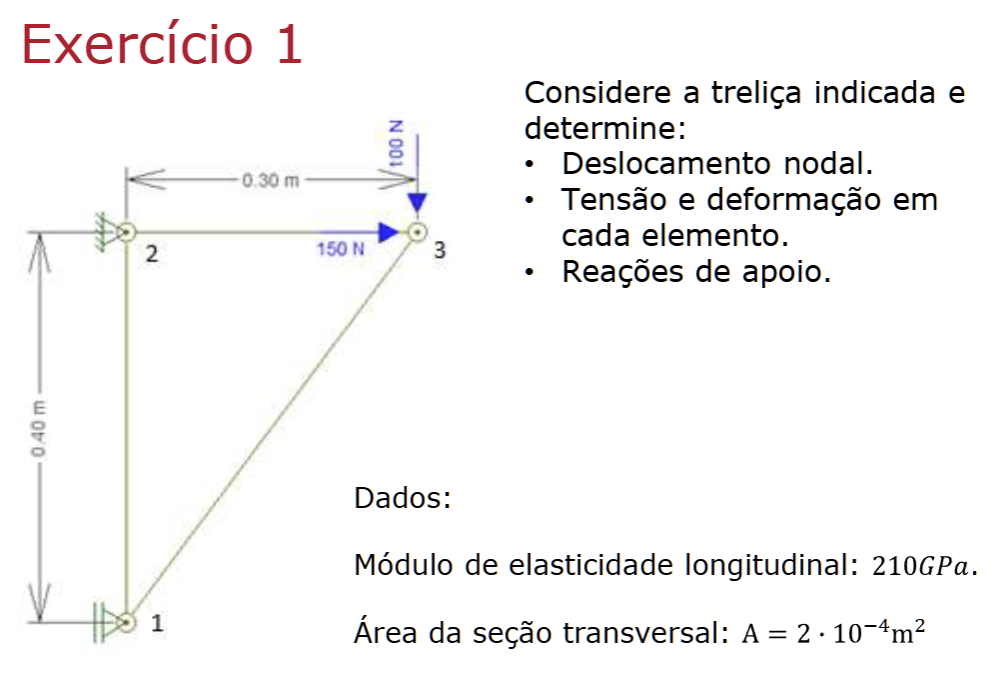

% PASSO 1: Definir a origem do sistema de referência e numerar os nós; elementos; GDL.

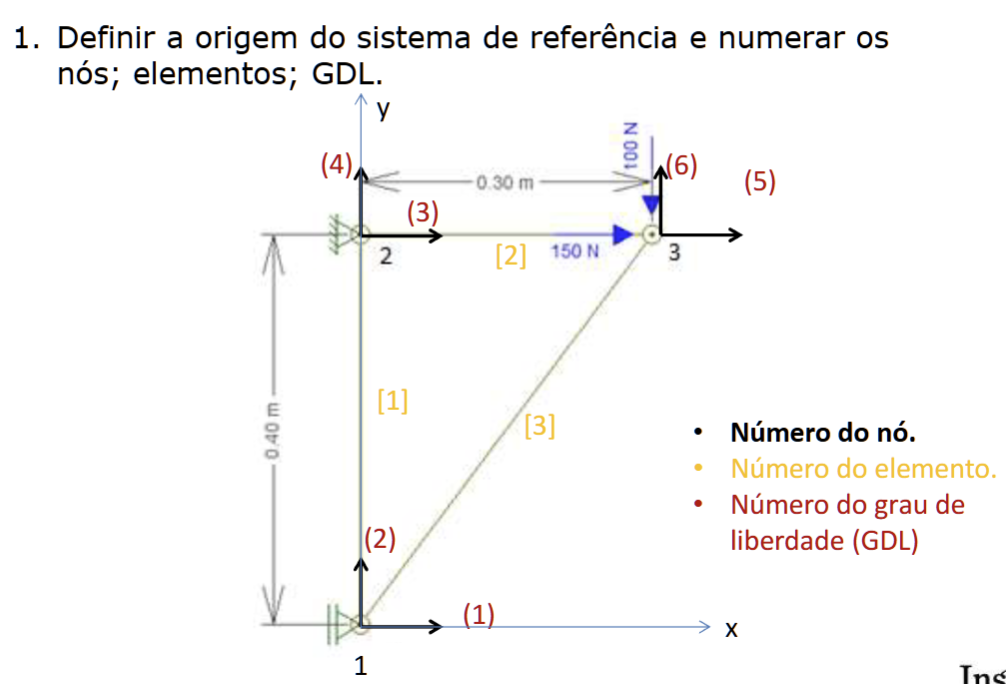

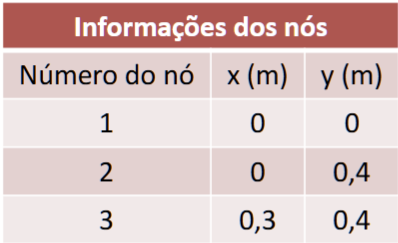

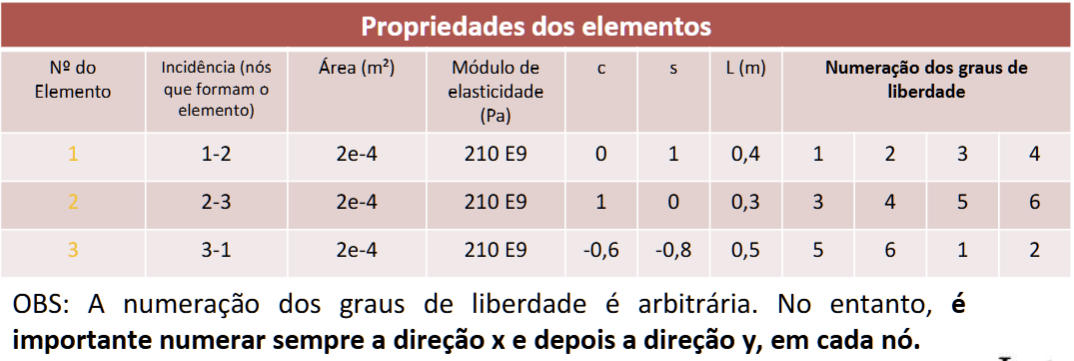

% PASSO 2: Montar a matriz de rigidez de cada elemento
E = 210 * 10^9;    % Módulo de elasticidade longitudinal [Pa]
A = 0.02 * 0.003;   % Área da seção transversal [m^2]
L = 5 * 10^(-2);   % Metade do comprimento de um elemento
h = 9.5 * 10^(-2); % altura

num_elementos = 25;
num_nos = 15;

% X e Y de cada nó
%       x    y
x_y = [ 0,   0; % Nó 1
        L,   h; % Nó 2 
        3*L, h; % Nó 3
        5*L, h% Nó 4
        7*L, h; % Nó 5
        9*L, h; % Nó 6
        11*L, h; % Nó 7
        12*L,   0; % Nó 8
        11*L,   0; % Nó 9
        10*L,   0; % Nó 10
        8*L,   0; % Nó 11
        6*L,   0; % Nó 12
        4*L,   0; % Nó 13
        2*L,   0; % Nó 14
        L,     0; % Nó 15
];

% Matriz de incidências de cada elemento
incidencias = [
    1, 2; % Elemento 1
    2, 3; % Elemento 2
    3, 4; % Elemento 3
    4, 5; % Elemento 4
    5, 6; % Elemento 5
    6, 7; % Elemento 6
    7, 8; % Elemento 7
    8, 9; % Elemento 8
    9, 10; % Elemento 9
    10, 11; % Elemento 10
    11, 12; % Elemento 11
    12, 13; % Elemento 12
    13, 14; % Elemento 13
    14, 15; % Elemento 14

    15, 1; % Elemento 15
    2, 14; % Elemento 16
    14, 3; % Elemento 17
    3, 13; % Elemento 18
    13, 4; % Elemento 19
    4, 12; % Elemento 20
    12, 5; % Elemento 21
    5, 11; % Elemento 22
    11, 6; % Elemento 23
    6, 10; % Elemento 24
    10, 7; % Elemento 25
];
% ============================================================================

% Comprimento dos elementos (e)
len_elementos = zeros(num_elementos, 1);

% ============================================================================

% Cossenos (c) e senos (s)
%c1 = 0; s1 = 1;
%c2 = 1; s2 = 0;
%c3 = (x1 - x3)/l3; s3 = (y1 - y3)/l3;

cos_sen = zeros(num_elementos, 2);  % cos_sen_el = [ c, s; 
%                                                      ...]

% ============================================================================

% Matrizes de Rigidez de cada elemento (K1, K2, K3, ...)
K = cell(num_elementos, 1);

% ============================================================================

% Calcular os comprimentos (L), os senos (s) e cossenos (c) e Matrizes de
% Rigidez (K)
for i = 1:num_elementos
    % Identificar os nós de cada elemento
    no1 = incidencias(i, 1);
    no2 = incidencias(i, 2);
    
    delta_x = x_y(no2,1) - x_y(no1,1);
    delta_y = x_y(no2,2) - x_y(no1,2);
    len = sqrt(delta_x^2 + delta_y^2);

    len_elementos(i) = len;               % tamanho elemento

    c = delta_x/len;                      % cosseno
    s = delta_y/len;                      % seno
    cos_sen(i,1) = c;
    cos_sen(i,2) = s;
    
    multiplicador = E*A/len;
    K{i} = multiplicador * [ c^2,   c*s, -c^2, -c*s;
                             c*s,   s^2, -c*s, -s^2;
                             -c^2, -c*s,  c^2,  c*s;
                             -c*s, -s^2,  c*s,  s^2 ];
end
% K
% VERIFICAR SE OS CALCULOS DE SENO E COSSENO FUNCIONAM PARA TODOS OS
% ELEMENTOS, se tiver mais nos


% PASSO 3: Montar a matriz de rigidez global [Kg] da treliça fazendo asuperposição das matrizes dos elementos.
num_gdl = num_nos*2;
Kg = zeros(num_gdl, num_gdl);

for i = 1:num_elementos

    % Monta a matriz de Kg
    no1 = incidencias(i, 1);
    no2 = incidencias(i, 2);

    % Graus de liberdade associados aos nós
    nos = [2*no1 - 1, 2*no1, 2*no2 - 1, 2*no2];

    Kg(nos, nos) = Kg(nos,nos) + K{i};
end
Kg;
% Amo a notação do Matlab, simplesmente uma escadinha de end

% PASSO 4: Montar o vetor global de forças. No grau de liberdade com restrição deve aparecer um esforço de reação.
Pg = zeros(num_nos*2, 1);

% Vou adicionar manualmente, pq n tem como automatizar isso
Pg(4*2) = -300;      % R4y
Pg(5*2) = -300;      % R5y

Pg

Pg =      0
     0
     0
     0
     0
     0
     0
  -300
     0
  -300


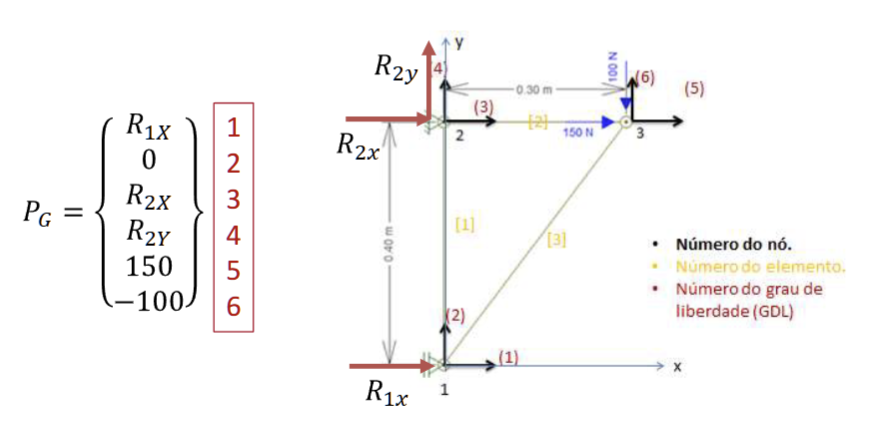

% PASSO 5: Aplicar as condições de contorno (eliminar linha e coluna do grau de liberdade com restrição)

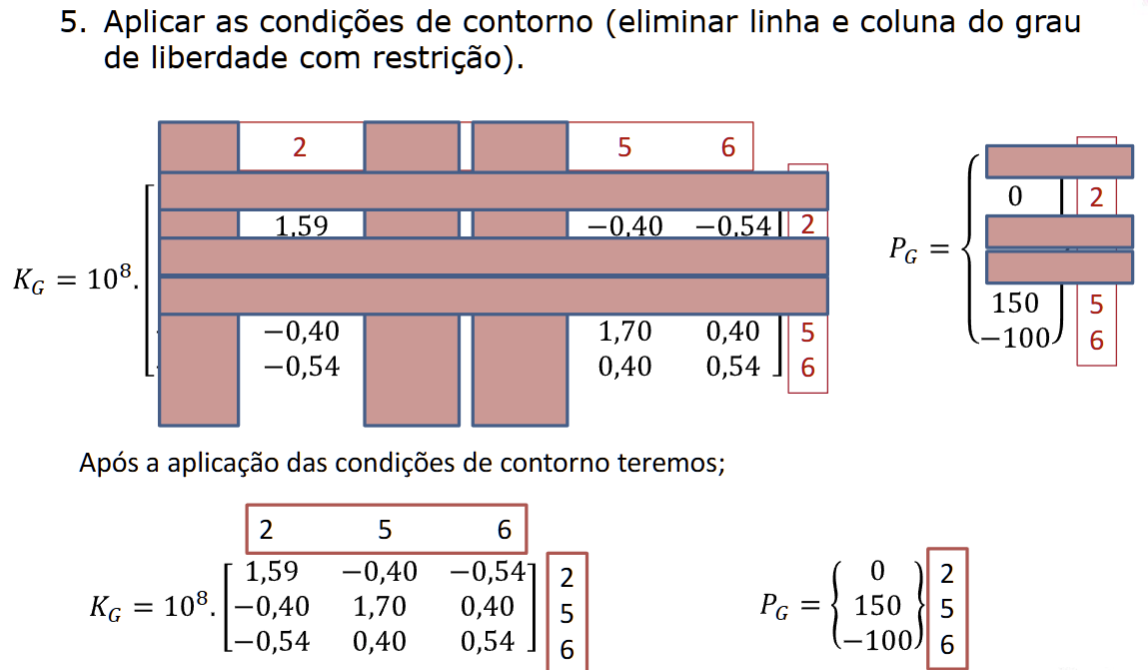

% Aplicando as condições de contorno, temos:
% pauloafe@insper.edu.br
restricao = [10*2 - 1, 10*2, 14*2-1, 14*2];  % R8x, R8y, R14x, R14y

Kg_reduzida = Kg;
Pg_reduzida = Pg;

% indexacao para colocar na matriz reduzida
Kg_reduzida(restricao, :) = [];
Kg_reduzida(:, restricao) = [];
Pg_reduzida(restricao) = [];

Kg_reduzida

Kg_reduzida =    2.7746e+08   4.8373e+07  -2.5459e+07  -4.8373e+07            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0  -2.5200e+08            0
   4.8373e+07   9.1909e+07  -4.8373e+07  -9.1909e+07            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0
  -2.5459e+07  -4.8373e+07   1.7692e+08            0  -1.2600e+08            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0         

Pg_reduzida

Pg_reduzida =      0
     0
     0
     0
     0
     0
     0
  -300
     0
  -300


% PASSO 6: Resolver o sistema de equações para a obtenção dos deslocamentos
%                      [Kg_reduzida] {U} = {Pg_reduzida}

U = Kg_reduzida \ Pg_reduzida;

U_expandida = zeros(num_nos*2, 1);
        
for row = 1:length(restricao)
    i = restricao(row);
    U_expandida(i) = U(row);
end
U_expandida

U_expandida =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


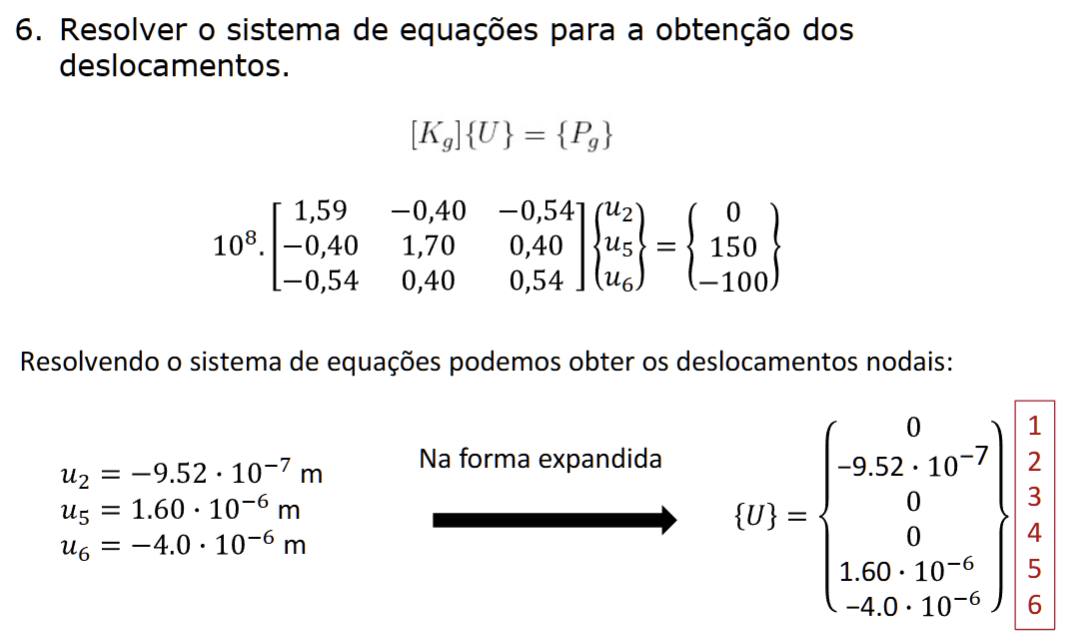

% PASSO 7: Determinar a deformação e a tensão em cada elemento.
deformacao = zeros(num_elementos, 1);  % como cada nó tem 2 u's
tensao = zeros(num_elementos, 1);  % como cada nó tem 2 u's

for i = 1:num_elementos
    c = cos_sen(i,1);
    s = cos_sen(i,2);
    
    if i == num_elementos
        aux = [U_expandida(2*i - 1);  U_expandida(2*i); U_expandida(1); U_expandida(2)];
    else
        index_u = (1 + 2*(i-1));
        aux = [U_expandida(index_u);  U_expandida(index_u+1); U_expandida(index_u+2); U_expandida(index_u+3)];
    end

    deformacao(i, 1) = (1/len_elementos(i,1)) * [-c, -s, c, s] * aux;
end

Index exceeds the number of array elements. Index must not exceed 30.


deformacao
tensoes = E * deformacao

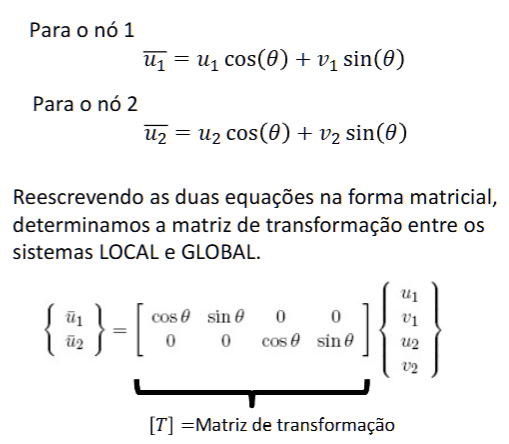

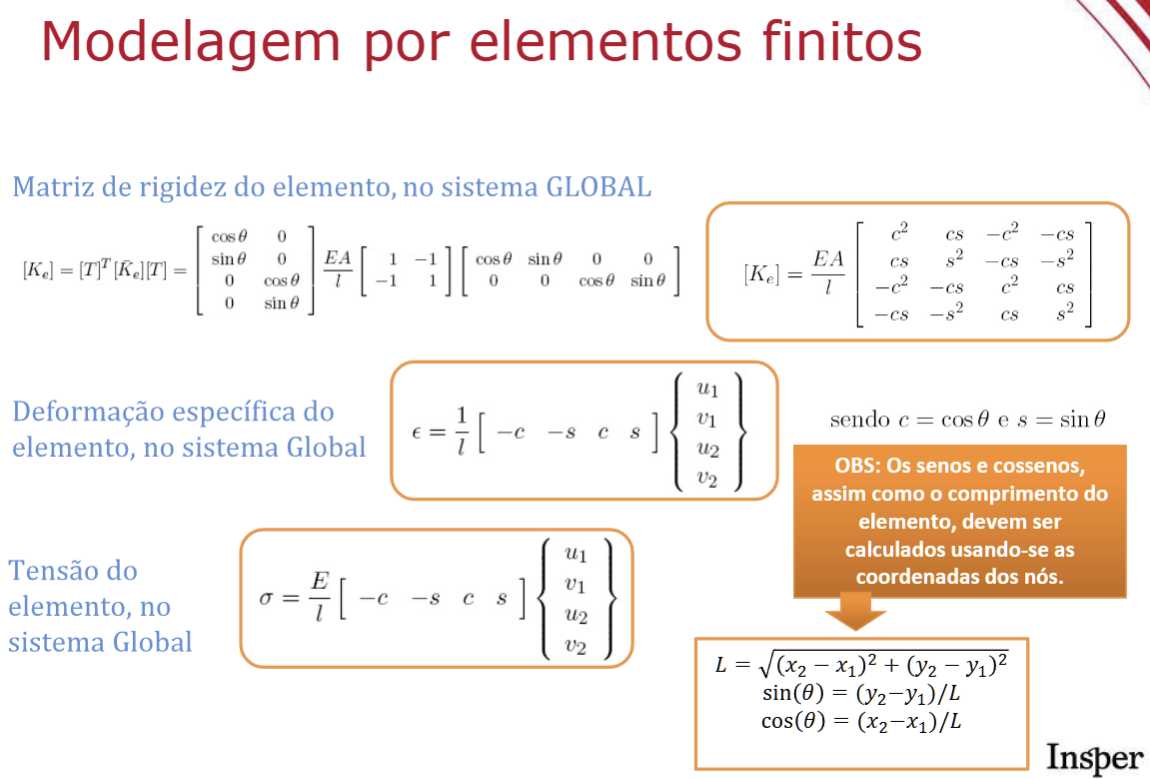

% PASSO 8: Determinar as reações de apoio nos nós com restrição.

Pg_final = Kg * U_expandida